# 2.2 离散时间信号与系统的时域分析：典型序列、周期性、卷积、稳定与因果

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：典型序列与周期性（教材 2.2.2、2.2.3）

预测：cos(0.3πn) 是周期序列吗？周期多少？cos(0.3n) 呢？

n = 0:59;
seqA = cos(0.3*pi*n);                              % 0.3π·N = 2πk → N = 20（k=3），周期序列
seqB = cos(0.3*n);                                 % 0.3·N = 2πk → N = 20πk/3，不是整数，不周期
expSeq = 0.8.^n .* (n >= 0);                       % 实指数序列
periodA = 20; periodicA = max(abs(seqA(1:40) - cos(0.3*pi*(n(1:40) + periodA)))) < 1e-12;
% cos(0.3n) 在任何 N≤200 都不严格重复
periodicB = false;
for N = 1:200, if max(abs(cos(0.3*(0:39)) - cos(0.3*((0:39) + N)))) < 1e-9, periodicB = true; end, end

## 演示2：卷积——翻转、平移、相乘、求和（教材 2.2.4）

预测：x=[1 2 3 4]（n=0..3）与 h=[3 2 1]（n=0..2）卷积有几点？y(2) 等于多少？

x = [1 2 3 4]; h = [3 2 1];
y = conv(x, h);                                    % 长度 4+3−1 = 6
yManual = zeros(1, 6);
for nn = 0:5
    for k = 0:3
        if nn-k >= 0 && nn-k <= 2, yManual(nn+1) = yManual(nn+1) + x(k+1)*h(nn-k+1); end
    end
end
showN = [0 2 4];                                   % 图上展示 h(n−k) 在三个 n 的位置

## 演示3：稳定性与因果性（教材 2.2.5）

Σ|h(n)| 有限才稳定；n<0 时 h(n)=0 才因果。

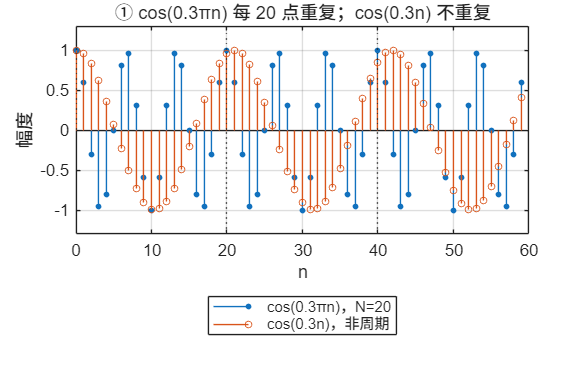

nn = -40:40;
hA = 0.8.^nn .* (nn >= 0);                         % 因果、稳定：Σ|h| = 1/(1−0.8) = 5
hB = 1.2.^nn .* (nn >= 0);                         % 因果、不稳定：Σ|h| 发散
hC = 0.8.^abs(nn);                                 % 稳定、非因果：n<0 也有值
cumA = cumsum(abs(hA)); cumB = cumsum(abs(hB)); cumC = cumsum(abs(hC));
stepIn = double(nn >= 0);                          % 有界输入 u(n)
yA = filter(1, [1 -0.8], stepIn);                  % 稳定系统的阶跃响应趋于 5
yB = filter(1, [1 -1.2], stepIn);                  % 不稳定系统的阶跃响应发散

if ~LIVE, f1 = figure('Name','01 序列与系统','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(n, seqA, 'filled', 'MarkerSize', 3); hold on; stem(n, seqB, 'MarkerSize', 4, 'Color', [0.85 0.33 0.1]);
xline(0:20:60, ':'); grid on; xlim([0 60]); ylim([-1.3 1.3]);
title('① cos(0.3πn) 每 20 点重复；cos(0.3n) 不重复'); xlabel('n'); ylabel('幅度');
legend('cos(0.3πn)，N=20','cos(0.3n)，非周期');

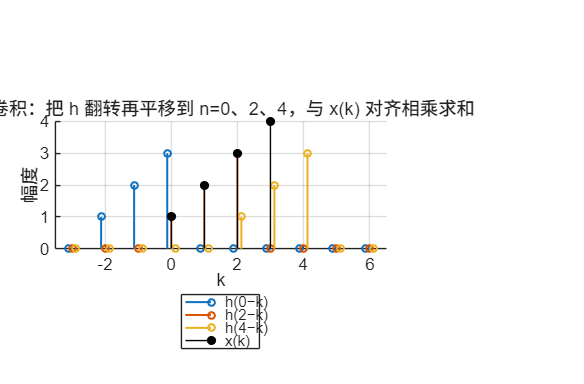

newpanel(); hold on; cols = lines(3);
for j = 1:3
    nn0 = showN(j); kk = -3:6;
    hflip = zeros(size(kk)); for i = 1:numel(kk), m = nn0 - kk(i); if m >= 0 && m <= 2, hflip(i) = h(m+1); end, end
    stem(kk + (j-2)*0.12, hflip, 'Color', cols(j,:), 'MarkerSize', 4, 'LineWidth', 1.2);
end
stem(0:3, x, 'k', 'filled', 'MarkerSize', 5); grid on; xlim([-3.5 6.5]);
title('② 卷积：把 h 翻转再平移到 n=0、2、4，与 x(k) 对齐相乘求和'); xlabel('k'); ylabel('幅度');
legend('h(0−k)','h(2−k)','h(4−k)','x(k)');

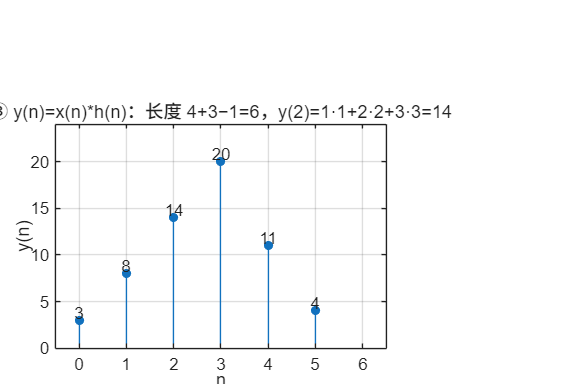

newpanel(); stem(0:5, y, 'filled', 'MarkerSize', 5); grid on; xlim([-0.5 6.5]); ylim([0 max(y)*1.2]);
text(0:5, y + 0.8, string(y), 'HorizontalAlignment', 'center');
title('③ y(n)=x(n)*h(n)：长度 4+3−1=6，y(2)=1·1+2·2+3·3=14'); xlabel('n'); ylabel('y(n)');

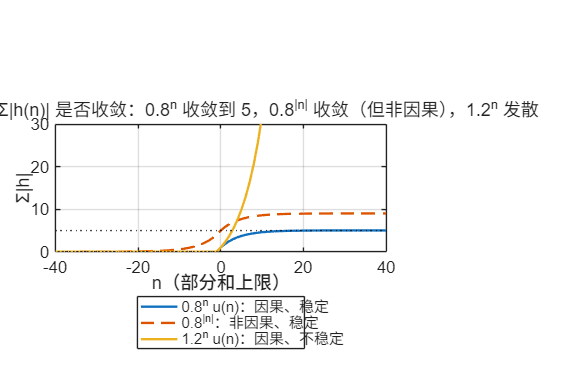

newpanel(); plot(nn, cumA, 'LineWidth', 1.4); hold on; plot(nn, cumC, '--', 'LineWidth', 1.4); plot(nn, cumB, 'LineWidth', 1.4);
yline(5, 'k:'); grid on; ylim([0 30]); xlim([-40 40]);
title('④ 稳定性看 Σ|h(n)| 是否收敛：0.8^n 收敛到 5，0.8^{|n|} 收敛（但非因果），1.2^n 发散');
xlabel('n（部分和上限）'); ylabel('Σ|h|'); legend('0.8^n u(n)：因果、稳定','0.8^{|n|}：非因果、稳定','1.2^n u(n)：因果、不稳定');

if ~LIVE, sgtitle('序列 → 周期性 → 卷积 → 稳定与因果：教材 2.2 的四件事'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '02-sequences-systems.png'), 'Resolution', 150); end

## 教师核验

assert(periodicA && ~periodicB, '周期性判断不符');
assert(isequal(y, yManual) && isequal(y, [3 8 14 20 11 4]), '卷积结果不符');
assert(abs(cumA(end) - 5) < 0.01 && cumB(end) > 1000 && abs(cumC(end) - 9) < 0.05, '稳定性判据不符');   % Σ0.8^{|n|} = 1 + 2·4 = 9
assert(abs(yA(end) - 5) < 0.01 && yB(end) > 1000, '阶跃响应不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'cos_0p3pi_period', periodA, 'cos_0p3_periodic', periodicB, 'x', x, 'h', h, 'conv', y, ...
    'sum_abs_h_0p8', cumA(end), 'sum_abs_h_1p2_partial', cumB(end), 'sum_abs_h_0p8_twosided', cumC(end), ...
    'step_response_final_stable', yA(end), 'step_response_final_unstable', yB(end), 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-sequences.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

                  matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                          run_at: '2026-09-18 19:30:20'
                cos_0p3pi_period: 20
                cos_0p3_periodic: 0
                               x: [1 2 3 4]
                               h: [3 2 1]
                            conv: [3 8 14 20 11 4]
                   sum_abs_h_0p8: 4.9995
           sum_abs_h_1p2_partial: 8.8136e+03
          sum_abs_h_0p8_twosided: 8.9989
      step_response_final_stable: 4.9995
    step_response_final_unstable: 8.8136e+03
               all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end